% Konstanten
v_min = 20 / 3.6;  % 20 km/h in m/s
v_max = 60 / 3.6;  % 60 km/h in m/s
v_pedestrian = 5 / 3.6;  % 5 km/h quer
bremskraft_min = 5.0;  % Mindestens 5 m/s²
ttc_warnung = 2.0;  % Warnung bei 2 Sekunden TTC
ttc_bremse = 1.2;   % Bremsen bei 1.2 Sekunden TTC

%Simulations Werte
time_step = 0.01;  % 0.01 Sekunden pro Schritt
gesamtzeit = 15;      % 15 Sekunden Simulation
zeit = 0:time_step:gesamtzeit;

% Auto Startposition und Geschwindigkeit
auto_x = 0;        % Auto bei Position x=0
auto_y = 0;        % Auto bei Position y=0  
v_ego = 50 / 3.6;  % 50 km/h Startgeschwindigkeit

% Fußgänger Startposition (35m vor Auto, 3m links)
pedestrian_x = 35;
pedestrian_y = -3;
pedestrian_gx = 0;  % Fußgänger bewegt sich nur in Y-Richtung

% Arrays für Ergebnisse (arrays werden erst nur aus nullen erstellt in der
% größe des gesamten Simulationszeitraums)
auto_position_x = zeros(size(zeit));
auto_position_y = zeros(size(zeit));
auto_geschwindigkeit = zeros(size(zeit));
pedestrian_position_x = zeros(size(zeit));
pedestrian_position_y = zeros(size(zeit));
ttc_werte = zeros(size(zeit));
warnung_aktiv = false(size(zeit));
bremse_aktiv = false(size(zeit));
bremskraft = zeros(size(zeit));
warnungs_start_zeit = zeros(size(zeit));

% Initialisiere erste Werte - Teilnehmer werden auf die "positionen" zu
% Beginnn der Simulation gesetzt
auto_position_x(1) = auto_x;
auto_position_y(1) = auto_y;
auto_geschwindigkeit(1) = v_ego;
pedestrian_position_x(1) = pedestrian_x;
pedestrian_position_y(1) = pedestrian_y;
ttc_werte(1) = Inf;


%% HAUPTSIMULATIONSSCHLEIFE
for i = 2:length(zeit)
    % PHYSIK & BEWEGUNG
    
    % 1. Geschwindigkeit holen (vom vorherigen Schritt)
    v_aktuell = auto_geschwindigkeit(i-1);
    
    % 2. Neue Positionen berechnen (x = x_alt + v * t)
    auto_position_x(i) = auto_position_x(i-1) + (v_aktuell * time_step);
    auto_position_y(i) = 0; % Auto fährt auf einer Spur
    
    % Fußgänger bewegt sich (v_pedestrian = 5 km/h)
    pedestrian_position_x(i) = pedestrian_x; % Bleibt bei -35m
    pedestrian_position_y(i) = pedestrian_position_y(i-1) + (v_pedestrian * time_step);
    
    
    % SENSORIK & LOGIK
    
    % 1. TTC berechnen
    ttc_werte(i) = berechne_ttc(auto_position_x(i), v_aktuell, pedestrian_position_x(i), pedestrian_position_y(i));
    
    % GESCHWINDIGKEITSPRÜFUNG
    system_aktiv = pruefe_geschwindigkeitsbereich(v_aktuell, v_min, v_max);
    if ~system_aktiv
      warnung_aktiv(i) = warnung_aktiv(i-1);
      bremse_aktiv(i) = bremse_aktiv(i-1);
      bremskraft(i) = bremskraft(i-1);
      auto_geschwindigkeit(i) = v_aktuell;
      continue;
    end

    % 2. Warnsystem
    warnung_alt_input = warnung_aktiv(i-1); % Hier übergeben wir den Zustand vom LETZTEN Schritt (i-1) als "warnung_alt"
    warnung_aktiv(i) = kollisionswarnung(warnung_alt_input, ttc_werte(i), ttc_warnung);
    
    % FCW ERWEITERTE WARNUNG (≥2 Modi: akustisch + optisch)
if warnung_aktiv(i) && ~warnung_alt_input
    % 1. AKUSTISCH (bereits in kollisionswarnung)
    fprintf('FCW WARNUNG: TTC=%.2f s (Pedestrian!)\n', ttc_werte(i));
    
    % 2. OPTISCH (gelb, blinkend, tagsichtbar 5.5.1/5.5.6)
    fprintf('OPTISCH: Gelbes Warnlicht BLINKT \n'); %(ECE R152 5.5.4)
    
    % Warn-Zeit für Analyse speichern
    warnungs_start_zeit(i) = zeit(i);
else
    % Warnung deaktiviert → optisches Licht AUS
    if warnung_alt_input && ~warnung_aktiv(i)
        fprintf('OPTISCH: Gelbes Warnlicht AUS\n');
    end
end
    
    % 3. Notbremsung
    bremse_alt_input = bremse_aktiv(i-1);
    kraft_alt_input  = bremskraft(i-1);
    
    [bremse_aktiv(i), bremskraft(i)] = notbremsung(bremse_alt_input, kraft_alt_input, ttc_werte(i), ttc_bremse, bremskraft_min);
    
    
    % FAHRZEUGREAKTION
    
    if bremse_aktiv(i)
        neue_v = v_aktuell - (bremskraft(i) * time_step); % Neue Geschwindigkeit berechnen (v = v_alt - a * t)
    else
        neue_v = v_aktuell; % Keine Änderung ohne Bremsen
    end
    
    % Verhindern, dass das Auto rückwärts fährt
    if neue_v < 0
        neue_v = 0;
    end
    
    auto_geschwindigkeit(i) = neue_v;
end

WARNUNG: TTC=1.79 s


FCW WARNUNG: TTC=1.79 s (Pedestrian!)


OPTISCH: Gelbes Warnlicht BLINKT 


NOTBREMSUNG: TTC=1.20 s



function [system_aktiv] = pruefe_geschwindigkeitsbereich(v, v_min, v_max) 
    if v >= v_min && v <= v_max % Prüft ob System aktiv sein muss (20-60 km/h)
        system_aktiv = true;
    else
        system_aktiv = false;
    end
end

function [ttc] = berechne_ttc(auto_x, auto_v, ped_x, ped_y)  % time to collision berechnen
    dx = ped_x - auto_x;
    dy = abs(ped_y);  % Abstand y (in Fahrbahnrichtg.)
    
    % Kollisionsgefahr nur wenn Fußgänger auf Fahrbahn (dy < 2m)
    if dy < 2.0
        if auto_v > 0
            ttc = abs(dx) / auto_v;
        else
            ttc = Inf; %wenn keine gefahr ttc ist INFinite
        end
    else
        ttc = Inf;
    end
end

function [warnung_neu] = kollisionswarnung(warnung_alt, ttc, ttc_warnung)
    % Kollisionswarnung Logik
    if ttc <= ttc_warnung && ~warnung_alt
        warnung_neu = true;
        fprintf('WARNUNG: TTC=%.2f s\n', ttc);
    elseif ttc > ttc_warnung + 0.5
        warnung_neu = false;  % Warnung abbrechen
    else
        warnung_neu = warnung_alt;
    end
end

function [bremse_neu, bremskraft_neu] = notbremsung(bremse_alt, bremskraft_alt, ttc, ttc_bremse, bremskraft_min)
    % Notbremsung Logik
    if ttc <= ttc_bremse && ~bremse_alt
        bremse_neu = true;
        bremskraft_neu = bremskraft_min;
        fprintf('NOTBREMSUNG: TTC=%.2f s\n', ttc);
    elseif bremse_alt && ttc > ttc_bremse + 0.5
        bremse_neu = false;
        bremskraft_neu = 0;  % Bremsung abbrechen
    else
        bremse_neu = bremse_alt;
        bremskraft_neu = bremskraft_alt;
    end
end



%% Integration Tests
fprintf('\n=== INTEGRATION TESTS ===\n');


=== INTEGRATION TESTS ===



% Test 1: Geschwindigkeitsbereich - System deaktiviert unter 20 km/h
test1_v = 15 / 3.6;  % 15 km/h < v_min
system1 = pruefe_geschwindigkeitsbereich(test1_v, v_min, v_max);
fprintf('Test 1 (v=15km/h): System %s (erwartet: false)\n', ...
    mat2str(system1));

Test 1 (v=15km/h): System false (erwartet: false)



% Test 2: Geschwindigkeitsbereich - System aktiv bei 50 km/h
test2_v = 50 / 3.6;
system2 = pruefe_geschwindigkeitsbereich(test2_v, v_min, v_max);
fprintf('Test 2 (v=50km/h): System %s (erwartet: true)\n', ...
    mat2str(system2));

Test 2 (v=50km/h): System true (erwartet: true)



% Test 3: TTC Berechnung - Fußgänger auf Kollisionskurs
ttc_test = berechne_ttc(0, 10, -20, 1.5);  % 20m entfernt, dy=1.5m
fprintf('Test 3 (TTC): %.2f s (erwartet: ~2.0s)\n', ttc_test);

Test 3 (TTC): 2.00 s (erwartet: ~2.0s)



% Test 4: Warnung aktiviert bei TTC < 2s
warn_test = kollisionswarnung(false, 1.8, ttc_warnung);

WARNUNG: TTC=1.80 s


fprintf('Test 4 (Warnung): %s (erwartet: true)\n', mat2str(warn_test));

Test 4 (Warnung): true (erwartet: true)



% Test 5: Bremsung aktiviert bei TTC < 1.2s
[bremse_test, kraft_test] = notbremsung(false, 0, 1.0, ttc_bremse, bremskraft_min);

NOTBREMSUNG: TTC=1.00 s


fprintf('Test 5 (Bremsung): %s, Kraft=%.1f (erwartet: true, 5.0)\n', ...
    mat2str(bremse_test), kraft_test);

Test 5 (Bremsung): true, Kraft=5.0 (erwartet: true, 5.0)



fprintf('=== TESTS ABGESCHLOSSEN ===\n\n');

=== TESTS ABGESCHLOSSEN ===



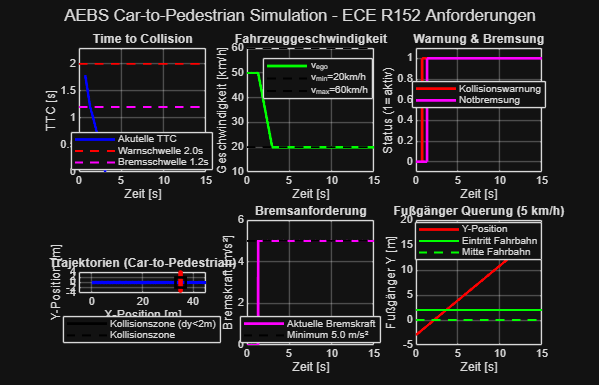


%% Visualisierung der Testergebnisse
figure('Position', [100 100 1400 900]);
sgtitle('AEBS Car-to-Pedestrian Simulation - ECE R152 Anforderungen');

% TTC und Schwellwerte (1)
subplot(2,3,1);
plot(zeit, ttc_werte, 'b-', 'LineWidth', 2, 'DisplayName', 'Akutelle TTC');
hold on;
plot(zeit, ttc_warnung*ones(size(zeit)), 'r--', 'LineWidth', 1.5, ...
     'DisplayName', 'Warnschwelle 2.0s');
plot(zeit, ttc_bremse*ones(size(zeit)), 'm--', 'LineWidth', 1.5, ...
     'DisplayName', 'Bremsschwelle 1.2s');
xlabel('Zeit [s]');
ylabel('TTC [s]');
title('Time to Collision');
legend('Location', 'best');
grid on;
ylim([0 max(ttc_werte(ttc_werte<Inf))+0.5]);

% Fahrzeuggeschwindigkeit (2)
subplot(2,3,2);
plot(zeit, auto_geschwindigkeit*3.6, 'g-', 'LineWidth', 2);
hold on;
plot(zeit, v_min*3.6*ones(size(zeit)), 'k--', 'LineWidth', 1.5);
plot(zeit, v_max*3.6*ones(size(zeit)), 'k--', 'LineWidth', 1.5);
xlabel('Zeit [s]');
ylabel('Geschwindigkeit [km/h]');
title('Fahrzeuggeschwindigkeit');
legend('v_{ego}', 'v_{min}=20km/h', 'v_{max}=60km/h', 'Location', 'best');
grid on;

% Warnung und Bremsung Status (3)
subplot(2,3,3);
stairs(zeit, double(warnung_aktiv), 'r-', 'LineWidth', 2, ...
       'DisplayName', 'Kollisionswarnung');
hold on;
stairs(zeit, double(bremse_aktiv), 'm-', 'LineWidth', 2, ...
       'DisplayName', 'Notbremsung');
xlabel('Zeit [s]');
ylabel('Status (1=aktiv)');
title('Warnung & Bremsung');
legend('Location', 'best');
grid on;
ylim([-0.1 1.1]);

% Trajektorien XY-Ebene (4)
subplot(2,3,4);
plot(auto_position_x, auto_position_y, 'b-', 'LineWidth', 3, ...
     'DisplayName', 'Auto');
hold on;
plot(pedestrian_position_x, pedestrian_position_y, 'ro', ...
     'MarkerSize', 3, 'MarkerFaceColor', 'r', 'DisplayName', 'Fußgänger'); 



hold on;
% Das eigentliche Rechteck zeichnen
rectangle('Position', [33, -2, 4, 4], 'EdgeColor', 'k', 'LineWidth', 2);

% Einen "Dummy"-Plot für die Legende erstellen (NaN Werte werden nicht gezeichnet)
rechteck_kasten = plot(NaN, NaN, 'k', 'LineWidth', 2, 'DisplayName', 'Kollisionszone (dy<2m)');

% Legende anzeigen
legend(rechteck_kasten);

% Legenden-Beschriftung
plot(NaN, NaN, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Kollisionszone');

xlabel('X-Position [m]');
ylabel('Y-Position [m]');
title('Trajektorien (Car-to-Pedestrian)');
legend('Location', 'best');
grid on;
axis equal;

% Der Blickwinkel wird nicht verändert
xlim([-5 45]); 
ylim([-4 4]);

% Bremskraft (5)
subplot(2,3,5);
plot(zeit, bremskraft, 'm-', 'LineWidth', 2);
hold on;
plot(zeit, bremskraft_min*ones(size(zeit)), 'k--', 'LineWidth', 1.5);
xlabel('Zeit [s]');
ylabel('Bremskraft [m/s²]');
title('Bremsanforderung');
legend('Aktuelle Bremskraft', sprintf('Minimum %.1f m/s²', bremskraft_min), ...
       'Location', 'best');
grid on;
ylim([0 max(bremskraft)+1]);

% Fußgänger Y-Position (zeigt Querung) (6)
subplot(2,3,6);
plot(zeit, pedestrian_position_y, 'r-', 'LineWidth', 2);
hold on;
plot(zeit, 2*ones(size(zeit)), 'g-', 'LineWidth', 1.5);
plot(zeit, 0*ones(size(zeit)), 'g--', 'LineWidth', 1.5);
xlabel('Zeit [s]');
ylabel('Fußgänger Y [m]');
title('Fußgänger Querung (5 km/h)');
legend('Y-Position', 'Eintritt Fahrbahn', 'Mitte Fahrbahn', 'Location', 'best');
grid on;


% Zusätzliche Analyse: Endgeschwindigkeit bei potenzieller Kollision
kollisionszeit = find(ttc_werte < 0.1, 1);
if ~isempty(kollisionszeit)
    end_v = auto_geschwindigkeit(kollisionszeit) * 3.6;
    fprintf('\nPotenzielle Kollisionsgeschwindigkeit: %.1f km/h\n', end_v);
else
    fprintf('\nKollision vermieden!\n');
end


Potenzielle Kollisionsgeschwindigkeit: 19.9 km/h



%% Speichere Ergebnisse für Testbericht
save('aebs_simulation_results.mat', 'zeit', 'auto_geschwindigkeit', ...
     'ttc_werte', 'warnung_aktiv', 'bremse_aktiv', 'bremskraft', ...
     'auto_position_x', 'pedestrian_position_y');
fprintf('Ergebnisse gespeichert: aebs_simulation_results.mat\n');

Ergebnisse gespeichert: aebs_simulation_results.mat
